# Opgave 1: sandsynlighedsregning

Ved en automatiseret test af chip-set på mobil-telefoner,

vil testen opdage en fejl, givet at chip-settet har en fejl, med en sandsynlighed på 34%.

Givet at chip-settet ikke har en fejl, vil testen indikere at det har en fejl med en sandsynlighed på 8%.

Sandsynligheden for at der er en fejl på et givet chip-set er 2,5%.

F = chip har fejl

F_invers = chip har ikke fejl

T = test opdager fejl

T_invers = Test opdager ikke fejl

**P(T|F) = 34%**

**P(T| F_invers)=8%**

**P(F) = 2.5%**

TGivetF=0.34;
TGivetFinv=0.08;
F=0.025;

**a) Hvad er sandsynligheden for at et chip-set både har en fejl og testen indikerer at det har en fejl?**

TestFejlOgChipFejl = TGivetF*F

TestFejlOgChipFejl = 0.0085

Sandsynligheden for både testen og chipsettet viser fejl er 0.85%

**b) Hvad er sandsynligheden for at et chip-set ikke har en fejl?**

**Vi ved at sandsynligheden for fejli i chipsæt er 2.5%. Trækkes det fra 100% finder vi sandsynligheden for ingen fejl.**

Finv = 1.0-0.025

Finv = 0.9750

**c) Hvis et tilfældigt chip-set bliver testet, hvad er sandsynligheden for at testen viser at det har en fejl (total sandsynlighed)?**

**Vi bruger formlen **$P\left(T\right)=P\left(T\cap F\right)+P\left(T\cap \bar{F} \right)=P\left(T\cap F\right)+P\left(T\left|\bar{F} \right.\right)*\bar{F}$

T=TestFejlOgChipFejl+TGivetFinv*Finv

T = 0.0865

**Sandsynligheden for at testen viser fejl på et tilfældigt chipsæt er 8.65%**

**d) Hvis testen viser at chip-settet har en fejl, hvad er sandsynligheden for at chip-settet rent faktisk havde en fejl?**

**Vi bruger formlen **$P\left(F\left|T\right.\right)=\frac{P\left(F\cap T\right)}{P\left(T\right)}$

FGivetT = TestFejlOgChipFejl/T

FGivetT = 0.0983

**Sandsynligheden for at chippen har fejl givet testen har en fejl er 9.83% **

# Opgave 2: Stokastiske variable

Den simultane tæthedsfunktion (pmf) for de diskrete stokastiske variable X og Y er givet ved:

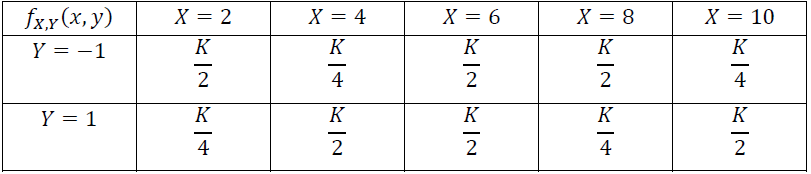

**a) Bestem K, så **$f_{x,y} \left(x,y\right)$**er en gyldig tæthedsfunktion.**

summen af alle sandsynligheder skal være 1, så derfor lægges de alle samen og k isoleres

syms k;
eqn = (k/2)+(k/2)+(k/2)+(k/2)+(k/2)+(k/2)+(k/4)+(k/4)+(k/4)+(k/4)==1;
soly = solve(eqn,k)

$$soly = \frac{1}{4}$$

Dette betyder at K skal være 1/4 for at tæthedfunktionen er gyldig.

**Antag at K=0,25 ved de efterfølgende opgaver.**

**b) Bestem og skitsér tæthedsfunktionen (pmf) fx(x) for X**

Ved antagelsen at K = 0.25 kan værdierne for de forskellige værdier af f(x) lægges sammen

k=0.25;
FX_2=(k/2)+(k/4)

FX_2 = 0.1875

FX_4=(k/4)+(k/2)

FX_4 = 0.1875

FX_6=(k/2)+(k/2)

FX_6 = 0.2500

FX_8=(k/2)+(k/4)

FX_8 = 0.1875

FX_10=(k/4)+(k/2)

FX_10 = 0.1875

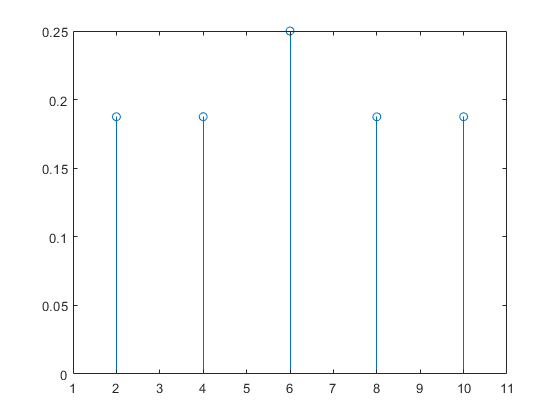

x = [2 4 6 8 10];
fx = [FX_2 FX_4 FX_6 FX_8 FX_10];
figure(1)
stem(x,fx);
set(gca, 'xlim', [1 11]);

**c) Find fordelingsfunktionen (cdf) Fx(x) for X.**

**vi starter af med at sætte grænser op. **


$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=0\;,\textrm{for}\;x<2$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=1\;,\textrm{for}\;x\ge 10$$


herefter kan vi finde cdf for grænserne


$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=2\right)=\frac{3}{16}\;,\textrm{for}\;2\le x<4$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=2\right)+P\left(X=4\right)=\frac{3}{16}+\frac{3}{16}=\frac{3}{8},\textrm{for}\;4\le x<6$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=2\right)+P\left(X=4\right)+P\left(X=6\right)=\frac{3}{16}+\frac{3}{16}+\frac{1}{4}=\frac{5}{8},\textrm{for}\;6\le x<8$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=2\right)+P\left(X=4\right)+P\left(X=6\right)+P\left(X=8\right)=\frac{3}{16}+\frac{3}{16}+\frac{1}{4}+\frac{3}{16}=\frac{13}{16},\textrm{for}\;8\le x<10$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=2\right)+P\left(X=4\right)+P\left(X=6\right)+P\left(X=8\right)+P\left(X=10\right)=\frac{3}{16}+\frac{3}{16}+\frac{1}{4}+\frac{3}{16}+\frac{3}{16}=1,\textrm{for}\;x\ge 10$$


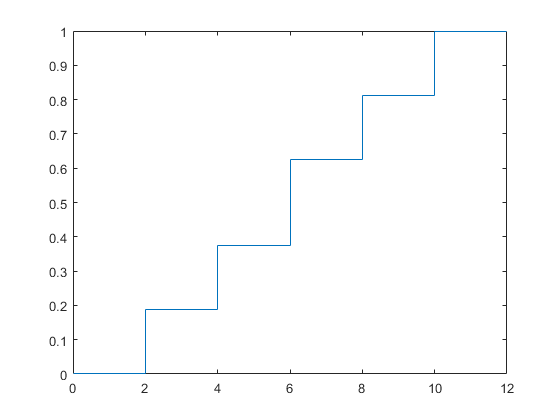

x=[0 2 4 6 8 10 12]; % udvidelsen med 12 er bare for at vise at den køre videre uden at ændre sig.
Fx=[0 3/16 3/8 5/8 13/16 1 1]; % udvidelsen med 1 er bare for at vise at den køre videre uden at ændre sig.
figure(2)
stairs(x,Fx);
set(gca, 'xlim', [0 12]);

**d) Opskriv formlerne til beregning af middelværdien og variansen af X og beregn disse.**

**middelværdi:**


$$E\left\lbrack X\right\rbrack \sum_x x*\textrm{fx}\left(x\right)=2*\frac{3}{16}+4*\frac{3}{16}+6*\frac{1}{4}+8*\frac{3}{16}+10*\frac{3}{16}=6$$


varians:


$$E\left\lbrack X^2 \right\rbrack \sum_x x^2 *\textrm{fx}\left(x\right)=4*\frac{3}{16}+16*\frac{3}{16}+36*\frac{1}{4}+64*\frac{3}{16}+100*\frac{3}{16}=\frac{87}{2}$$



$$\textrm{Var}\left(x\right)=$$

$$E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 =\frac{87}{2}-36=\frac{15}{2}=7\ldotp 5$$


**Middelværdi er 6 og varians er 7.5**

**e) Opstil formlen for og find E[XY]**


$$E\left\lbrack \textrm{XY}\right\rbrack \sum_x x*y*\textrm{fx}\left(x,y\right)=1*2*\frac{k}{4}+1*4*\frac{k}{2}+1*6*\frac{k}{2}+1*8*\frac{k}{4}+1*10*\frac{k}{2}-1*2*\frac{k}{2}-1*4*\frac{k}{4}-1*6*\frac{k}{2}-1*8*\frac{k}{2}-1*10*\frac{k}{4}=\frac{1}{4}$$


**f) Bestem den betingede sandsynlighed Pr(X=1|Y=6)**

**vi bruger følgende formel for betinget sandsynlighed**


$$P\left(X\left|Y\right.\right)=\frac{P\left(X\cap Y\right)}{P\left(Y\right)}=\frac{\frac{k}{2}}{\frac{k}{2}+\frac{k}{2}}=\frac{\frac{0\ldotp 25}{2}}{\frac{0\ldotp 25}{2}+\frac{0\ldotp 25}{2}}=\frac{\frac{1}{8}}{\frac{1}{4}}=\frac{1}{2}$$


**den betingede sandsynlighed for at Pr(X=1|Y=6) er 1/2**

# Opgave 3: Stokastiske processer

En tids-diskret stokastisk proces X[n] er defineret som:


$$X\left\lbrack n\right\rbrack =-1\ldotp 5*\left(Z\left\lbrack n\right\rbrack +1\right)$$


hvor $Z\left\lbrack n\right\rbrack ~N\left(1,10\right)$(1,10) er i.i.d. (uafhængigt og ens fordelt).

**a) Plot tre realisationer af processen X[n] for n=[1,⋯,10]. Brug en tilfældighedsgenerator og vis med kode (Matlab, Maple, Prime, Pyton el.lign.) hvordan realisationen er fremkommet. I Matlab kan randn() benyttes.**

Xn =    -2.4777   -4.7596   -8.2016   -1.1113   -2.5946  -14.2575   -0.7520   -7.4889   -6.8809  -10.5372


TidsligMiddel = -5.9061

Xn =    -5.4951    8.6935    1.0439   -5.4274   -4.2227  -12.3087   -9.6707   -5.3567   -3.3929    4.3451


TidsligMiddel = -3.1792

Xn =   -11.8377   -3.6357    4.3333   -5.0552   -3.4884   -0.2946   -5.3388    0.3560    3.3942    5.3214


TidsligMiddel = -1.6245

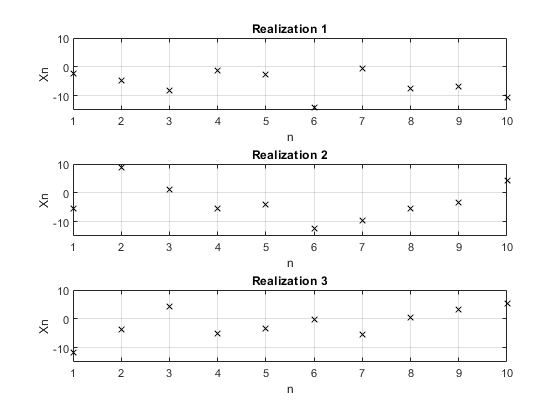

%Three realizations Ten samples
sigma = 10;
mu = 1;
for i=1:3 %1:3 because we need 3 realizations
    Xn=-1.5*((randn(1,10)*sqrt(sigma)+1)+1)%Why +1?
    TidsligMiddel = sum(Xn)/10
    figure(3)
    ax=subplot(3,1,i);%3 realizations plot
    n=1:10;%10 samples between 10-1
    plot(ax,n,Xn,'kx')
    grid
    axis([1,10,-15,10])%set values(length) for x and y axis
    title(ax,['Realization ',num2str(i)])%axis title
    xlabel(ax,'n');
    ylabel(ax,'Xn');
end

**b) Opstil formlen for og find den tidslige middel for én af de plottede realisationer.**

**Den tidslige middel kan ses i opgave 3a)**

**c) Bestem ensemble middelværdien og variansen for processen X[n].**

 Ved at tage middelværdien for de individuelle dele og gange dem på findes middelværdien for EXn

Ez=1;%Gausisk normalfordeling (mu)
EXn=(-1.5)*(Ez+1)%Middel værdien for Z[n] er 1. formlen siger -1.5*(Z[n]+1), derfor ender ensemble middelværdien med at være -3

EXn = -3

Det samme gør sig gældene for variansen

Varz=10;%Gausisk normalfordeling (sigma^2)
VarYn=((-1.5)^2)*Varz

VarYn = 22.5000

**d) Er processen X[n] WSS (stationær i den bredde forstand)? Svaret skal begrundes.**

I det er der ikke er noget aspekt af tid i processen X[n], betyder det at X[n] er WSS.

Så ja X[n] er WSS

# Opgave 4: Statistik

Et barn’s højde måles i faste intervaller til:

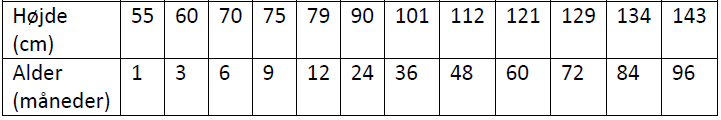

**a) Opstil signal-modellen for data, under antagelse af at der er en lineær sammenhæng mellem data, med overlagt i.i.d. (uafhængigt og ens fordelt) normalfordelt støj.**

**formlen for en linær funktion med støj taget i betragtning er **$Y=\beta_0 +\beta_1 \cdot x+\varepsilon$

I det at der antages en sammen hæng mellem alder og højde kan vi stille formlen og således $H=\beta_0 +\beta_1 \cdot A+\varepsilon$, varepsilon betegner støjen hvilket betyder at der tages højde for fejl i approximationen.

*signal modellen er vist forneden *


$$H=\beta_0 +\beta_1 \cdot A+\varepsilon$$


Kan også skrives således 


$$H=\alpha +\beta \cdot A+\varepsilon$$


$\varepsilon$ er en gausisk (normal) fordeling $N\left(0,\sigma^2 \right)$

Height_cm = [55,60,70,75,79,90,101,112,121,129,134,143];
Age_month = [1,3,6,9,12,24,36,48,60,72,84,96];


**b) Under antagelse af at der er en lineær sammenhæng mellem data, find den lineære regressions-linie, ved at udregne hældningen og skæringen.**

**for udregning af hældning og skæring skal mu for højden og mu for alderen udregnes først det gøres ved de viste formler**


$$\mu {\;}_h =\frac{1}{12}\cdot \sum_{i=1}^{12} h_i$$


mu_height=(1/12)*sum(Height_cm)

mu_height = 97.4167


$$\mu {\;}_a =\frac{1}{12}\cdot \sum_{i=1}^{12} a_i$$


mu_age=(1/12)*sum(Age_month)

mu_age = 37.5833

nu kan beta og alfa findes ved neden stående formler


$$\beta =\frac{\sum_{i=1}^{12} \left(a_i -\mu {\;}_a \right)\cdot \left(h_i -\mu {\;}_{h\;} \right)}{\sum_{i=1}^{12} {\left(a_i -\mu {\;}_a \right)}^2 }$$


for at udføre udregnignen i matlab opdeles tæller og nævner og regnes ud alene. herefter divideres de sammen.

beta_taeller= 0;
beta_naevner= 0;
for n=1:length(Age_month)%der er samme mængde data for alder og højde så det gør ikke nogen forskel hvilken der bruges
    beta_taeller = beta_taeller + (Age_month(n)-mu_age)*(Height_cm(n)-mu_height);
    beta_naevner = beta_naevner + (Age_month(n)-mu_age).^2;% every element is taken to the power of 2
end
beta = beta_taeller/beta_naevner%Dette er hældningen

beta = 0.8800

alfa findes ved at bruge nedenstående formel


$$\alpha =\mu {\;}_h -\beta \cdot \mu {\;}_a$$


alpha = mu_height-beta*mu_age%dette er skæringen

alpha = 64.3418

vi har nu fundet hældningen og skæringen og kan skrive formlen for den bedste rette linje således


$$H=64\ldotp 34+0\ldotp 88\cdot A+\varepsilon$$
 

Skæringen er 64.34

hældnignen er 0.88

**c) Opstil en hypotese og en alternativ hypotese, der tester om hældingen er 0.**

 H0: $\beta \;=0$, Hældning er 0

 H1: $\beta \not= 0$, hældning er ikke 0

**d) Kan nul-hypotesen afvises med et signifikans-niveau på 5%?**


$$S_r^2 =\frac{1}{n-2}\cdot \;\sum_{i=1}^n {\left(y_i -\left(\alpha +\beta \cdot x_i \right)\right)}^2$$


sr2=(1)/(length(Age_month)-2)*sum((Height_cm-(alpha+beta*Age_month)).^2);


$$S_{\mathrm{xx}} =\;\sum_{i=1}^n {\left(x_i -\overline{x} \right)}^2$$


sxx=sum((Age_month-mu_age).^2);

Hnull_beta0=0;


$$t=\frac{\beta -\beta {\;}_{0\;} }{\sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}}$$


t=(beta- Hnull_beta0)/(sqrt(sr2/sxx));


$$\mathrm{pval}=2*\left(1-t_{\mathrm{cdf}} \left(|t|,n-2\right)\right)$$


p=2*(1-tcdf(abs(t),length(Age_month)-2))

p = 8.3250e-09

I det at p-værdien er meget under 0.05 betyder det at vi kan afvise nulhypotesen.

H0 er afvist, som betyder at $\beta {\;}_0 \not= 0$

**e) Bestem 95% konfidens intervallet for hældningen? Hvad fortæller konfidens-intervallet?**

vi bruger formlen 


$$t_0 =\mathrm{tinv}\left(1-\frac{0\ldotp 05}{2},n-2\right)=\mathrm{tinv}\left(0\ldotp 975,n-2\right)$$


t0=tinv(0.975,length(Age_month)-2)

t0 = 2.2281

herefter kan den nedre og øvre grænse findes


$${\beta \;}_- =\beta -t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}$$


Beta_nedre=beta-t0*sqrt(sr2/sxx)

Beta_nedre = 0.7674


$${\beta \;}_+ =\beta +t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\mathrm{xx}} }}$$


Beta_oevre=beta+t0*sqrt(sr2/sxx)

Beta_oevre = 0.9927

Konfidens intervalelt fortæller os at betas nedre værdi er større end nullhypotesen.

Dette betyder at vi igen kan afvise nullhypotesen og bekræfte at hældningen ikke er ligmed 0.

**f) Plot residualerne (residualplottet) efter lineær regression. Ser det ud som om der er en lineær sammenhæng mellem alder og højde?**

Tager vi den originale formel 


$$H=\alpha +\beta \cdot A+\varepsilon$$


kan vi isolere epsilon, og ender derfor med 


$$\varepsilon {\;}_i =H_i -\alpha +\beta \cdot A_i$$


epsilon1 = Height_cm(1)-(alpha+(beta*Age_month(1)));
epsilon2 = Height_cm(2)-(alpha+(beta*Age_month(2)));
epsilon3 = Height_cm(3)-(alpha+(beta*Age_month(3)));
epsilon4 = Height_cm(4)-(alpha+(beta*Age_month(4)));
epsilon5 = Height_cm(5)-(alpha+(beta*Age_month(5)));
epsilon6 = Height_cm(6)-(alpha+(beta*Age_month(6)));
epsilon7 = Height_cm(7)-(alpha+(beta*Age_month(7)));
epsilon8 = Height_cm(8)-(alpha+(beta*Age_month(8)));
epsilon9 = Height_cm(9)-(alpha+(beta*Age_month(9)));
epsilon10 = Height_cm(10)-(alpha+(beta*Age_month(10)));
epsilon11 = Height_cm(11)-(alpha+(beta*Age_month(11)));
epsilon12 = Height_cm(12)-(alpha+(beta*Age_month(12)));

residualplots=[epsilon1,epsilon2,epsilon3,epsilon4,epsilon5,epsilon6,epsilon7,epsilon8,epsilon9,epsilon10,epsilon11,epsilon12]

residualplots =   -10.2218   -6.9819    0.3780    2.7378    4.0977    4.5372    4.9767    5.4162    3.8557    1.2953   -4.2652   -5.8257


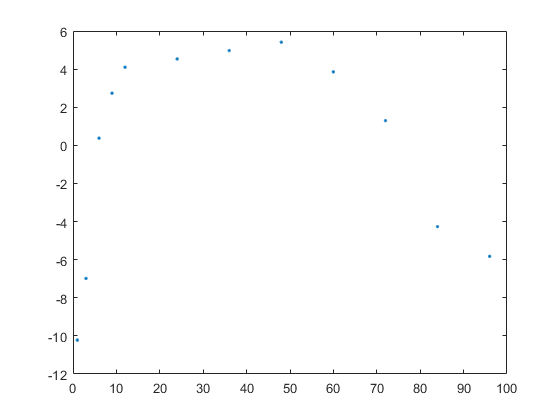

figure(4)
plot(Age_month,residualplots,'.')

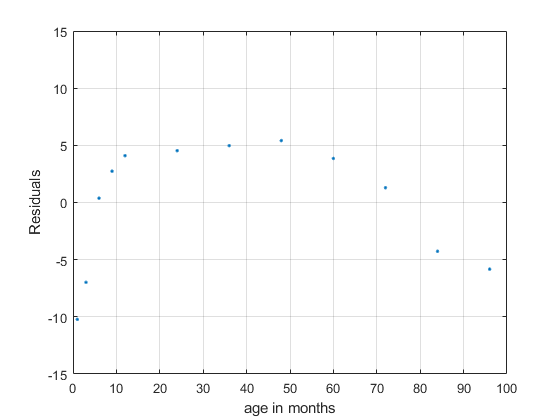

epsilon = Height_cm-(alpha+(beta*Age_month));
figure(7)
plot(Age_month,epsilon,'.')
axis([0 100 -15 15])
xlabel('age in months')
ylabel('Residuals')

grid on

De tog metoder giver det samme svar

det vi kan se på graferne er at der er et mønster i dem. Havde punkterne lagt tilfældigt ville man ud fra graffen kunne sige at der er en linær sammenhæng mellem alder og højde. 

I det at der er et mønster som ligner et inverteret U **kan vi antage at der ikke er en linæer sammenhæng mellem alder og højde.** Dette betyder at en ikke linæer model ville være mere passende at bruge istedet.

**Endelige svar er Det ser ikke ud til at der er linæer sammenhæng mellem alder og højde**